clear
im1=double(imread("image6.png"))/255;
%imshow(im1)

im1r=im1(:,:,1); im1g=im1(:,:,2); im1b=im1(:,:,3);
%imshow(im1r), figure, imshow(im1g), figure, imshow(im1b)

im1ycbcr=rgb2ycbcr(im1);
im1y=im1ycbcr(:,:,1); im1cb=im1ycbcr(:,:,2); im1cr=im1ycbcr(:,:,3); 
imshow(im1y), figure
%imshow(im1cb), figure, imshow(im1cr)

% % Chrominance Subsample
% factor = 0.5;
% 
% im1cb2 = imresize(im1cb, factor);
% im1cr2  = imresize(im1cbr, factor);
% 
% im1cbr = imresize(im1cb2r, 1/factor);
% im1crr = imresize(im1cbrr, 1/factor);

% DCT transform
im1yd = bdct(im1y, [8 8]);
im1Cbd = bdct(im1cb, [8 8]);
im1Crd = bdct(im1y, [8 8]);

% Quantization

% Scalar 
% Q1=0.5;
% im1ydq = bquant(im1yd, Q1);
% im1ydr = brec(im1ydq, Q1);
% im1yr = ibdct(im1ydr, [8 8], [512 768]);
% figure, imshow(im1yr);

% Vector
QL=repmat(1:8, 8, 1); 
QL=(QL+QL-9)/8;
k1 = 0.1; 
k2 = 0.3; 
Q2 = k1 * (1 + k2 * QL);
im1ydq = bquant(im1yd, Q2);
im1ydr = brec(im1ydq, Q2);
im1yr = ibdct(im1ydr, [8 8], [512 768]);
figure, imshow(im1yr);

dist = mean((im1y(:)-im1yr(:)).^2)
psnr = 10*log10(1/dist) % There is no standard way of defoning distortion and PSNR for colour images. The simplest way is to just average the distortions of the three colour components (red, green and blue).

% Coding

% Huffman
p = ihist(im1ydq(:)); 
bits = huffman(p)
bpp = bits/(512*768)

%Jpgrate
bits=sum(jpgrate(im1ydq, [8 8]))

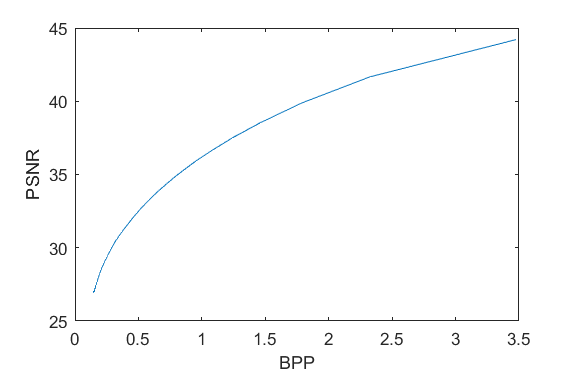

clear
clf()

im1=double(imread("image6.png"))/255;

steps = 0.7:-0.01:0.01;

psnrs = zeros(size(steps));
bpps = zeros(size(steps));

for i=1:length(steps)
    [psnr, bpp] = transcoder(im1, steps(i));
    psnrs(i) = psnr;
    bpps(i) = bpp;
    
end

plot(bpps, psnrs)
xlabel("BPP"); ylabel("PSNR")

hold on

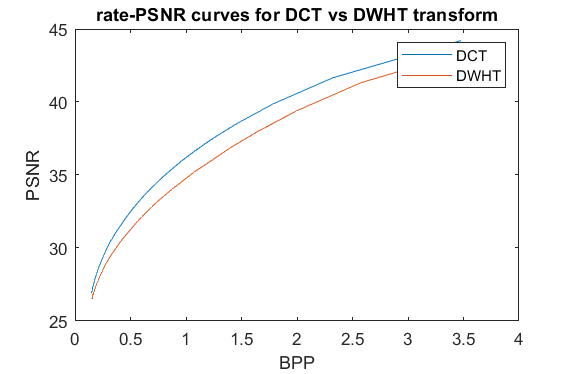

for i=1:length(steps)
    [psnr, bpp] = transcoder(im1, steps(i));
    psnrs(i) = psnr;
    bpps(i) = bpp;
    
end

plot(bpps, psnrs)
legend("DCT", "DWHT")

title("rate-PSNR curves for DCT vs DWHT transform")

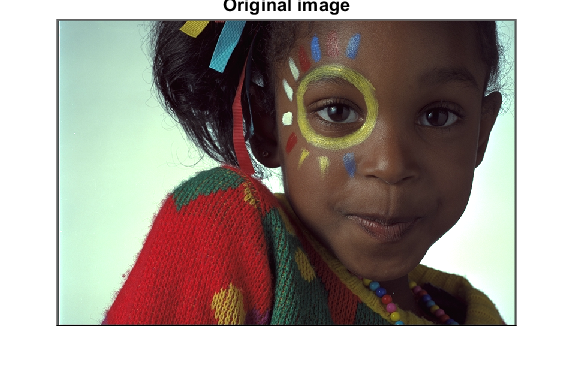

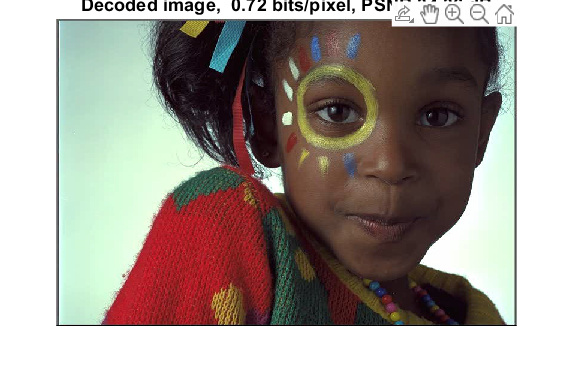

ans = 34.3588

transcoder(im1, 0.1)